clear
close all

## Preámbulo

d = @(t) t==0;
u = @(t) t>=0;

N = 400;

## Resolución

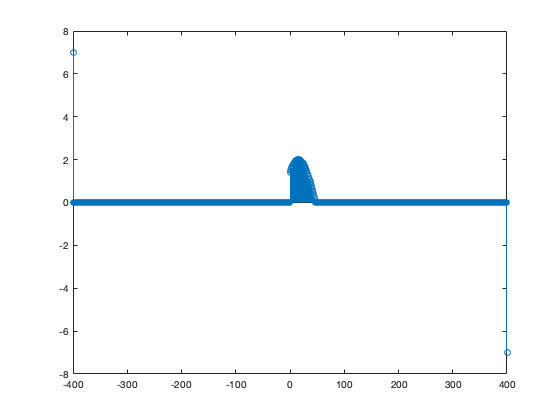

n= -N:N;

p1 = @(n) 10E-4*(-n.^2 + 3600)/5;
ojo_antes = @(n) (u(n+60) - u(n-60)).*(cos(100*n) .* cos(n));
ojo_despues = @(n) ojo_antes(n) .* (abs(ojo_antes(n))<=p1(n));

m= @(n) 7*d(n+N)-7*d(n-N);

la = @(n) (u(n) - u(n-(pi-pi/4)/(10E-2))).*cos(10E-2*n-pi/4);
ld = @(n) (-1).^(n) .* (la(n) + la(-n))/2 - 1/3*d(n);
% figure
% plot(n,p1(n))
figure
stem(n,m(n) + 2*la(n/2))

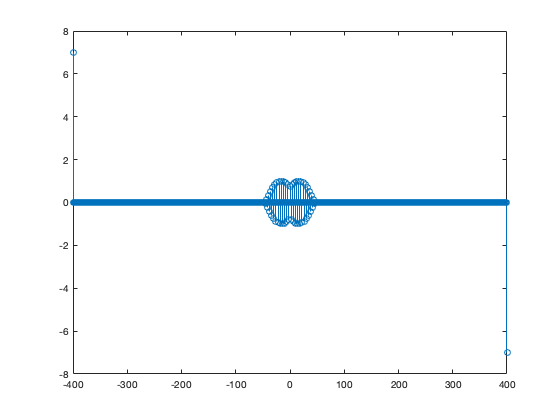

figure
stem(n,m(n) + 2*ld(n/2))

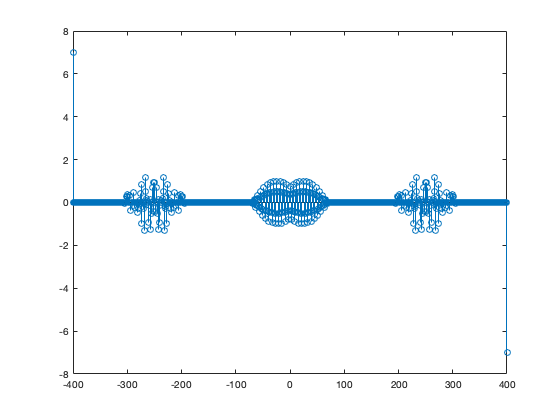


figure
stem(n,real(m(n)+2*ojo_despues(n-250)+2*ojo_despues(n+250)+2*ld(n/3)))